Proyecto

data = readtable('data/base/count_per_month.csv')

data = 79×2 table
    releaseDate    cant
    ___________    ____

    {'2010-02'}     1  
    {'2010-09'}     1  
    {'2010-10'}     1  
    {'2010-12'}     2  
    {'2011-02'}     1  
    {'2011-08'}     1  
    {'2011-10'}     1  
    {'2011-11'}     1  
    {'2011-12'}     1  
    {'2012-08'}     4  
    {'2012-09'}     1  
    {'2012-10'}     2  
    {'2012-11'}     5  
    {'2012-12'}     1  
    {'2013-02'}     1  
    {'2013-03'}     2  


% Probando con las fechas
%datetime(,'InputFormat','yyyy/MM/dd HH:mm:ss.S')
date = data{1,"releaseDate"}

date = 1×1 cell array
    {'2010-02'}


class(date)

ans = 'cell'

datetime(datatable{:,'releaseDate'},'InputFormat','yyyy-MM')

ans = 79×1 datetime array
   01-Feb-2010
   01-Sep-2010
   01-Oct-2010
   01-Dec-2010
   01-Feb-2011
   01-Aug-2011
   01-Oct-2011
   01-Nov-2011
   01-Dec-2011
   01-Aug-2012
   01-Sep-2012
   01-Oct-2012
   01-Nov-2012
   01-Dec-2012
   01-Feb-2013
   01-Mar-2013
   01-Apr-2013
   01-May-2013
   01-Nov-2013
   01-Dec-2013
   01-Jan-2014
   01-Apr-2014
   01-May-2014
   01-Jul-2014
   01-Oct-2014
   01-Feb-2015
   01-Apr-2015
   01-May-2015
   01-Jun-2015
   01-Jul-2015


% Probando la clase MobileAppDataset
objDataset = MobileAppDataset()

objDataset =   MobileAppDataset with no properties.


objDataset.getCountPerMonthTable()

ans = 79×2 table
    releaseDate    cant
    ___________    ____

    {'2010-02'}     1  
    {'2010-09'}     1  
    {'2010-10'}     1  
    {'2010-12'}     2  
    {'2011-02'}     1  
    {'2011-08'}     1  
    {'2011-10'}     1  
    {'2011-11'}     1  
    {'2011-12'}     1  
    {'2012-08'}     4  
    {'2012-09'}     1  
    {'2012-10'}     2  
    {'2012-11'}     5  
    {'2012-12'}     1  
    {'2013-02'}     1  
    {'2013-03'}     2  


% Accediendo a datos con expresiones
datatable = objDataset.getCountPerMonthTable();
datatable{1,'releaseDate'}{:}

ans = '2010-02'

% Método getCountPerMonth() de la clase MobileAppDataset
[fechas, cantidades] = objDataset.getCountPerMonth()

fechas = 79×1 datetime array
   01-Feb-2010
   01-Sep-2010
   01-Oct-2010
   01-Dec-2010
   01-Feb-2011
   01-Aug-2011
   01-Oct-2011
   01-Nov-2011
   01-Dec-2011
   01-Aug-2012
   01-Sep-2012
   01-Oct-2012
   01-Nov-2012
   01-Dec-2012
   01-Feb-2013
   01-Mar-2013
   01-Apr-2013
   01-May-2013
   01-Nov-2013
   01-Dec-2013
   01-Jan-2014
   01-Apr-2014
   01-May-2014
   01-Jul-2014
   01-Oct-2014
   01-Feb-2015
   01-Apr-2015
   01-May-2015
   01-Jun-2015
   01-Jul-2015


cantidades =      1
     1
     1
     2
     1
     1
     1
     1
     1
     4


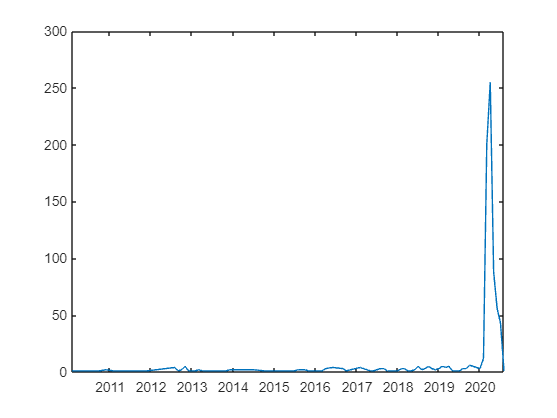

plot(fechas, cantidades)

% Configuración de MATLAB con Python
pathExe = horzcat(pwd,'\env\Scripts\python.exe');
pyenv('Version',pathExe)

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Users\Tiber\Mis Archivos\Repositorios\GitHub\UTPL\proyecto-final-b-da8ah\env\Scripts\python.exe"
          Library: "C:\Users\Tiber\AppData\Local\Programs\Python\Python39\python39.dll"
             Home: "C:\Users\Tiber\Mis Archivos\Repositorios\GitHub\UTPL\proyecto-final-b-da8ah\env"
           Status: NotLoaded
    ExecutionMode: InProcess


py.help('pandas')

C:\Users\Tiber\AppData\Local\Programs\Python\Python39\lib\inspect.py:351: FutureWarning: pandas.Float64Index is deprecated and will be removed from pandas in a future version. Use pandas.Index with the appropriate dtype instead.
  value = getattr(object, key)
C:\Users\Tiber\AppData\Local\Programs\Python\Python39\lib\inspect.py:351: FutureWarning: pandas.Int64Index is deprecated and will be removed from pandas in a future version. Use pandas.Index with the appropriate dtype instead.
  value = getattr(object, key)
C:\Users\Tiber\AppData\Local\Programs\Python\Python39\lib\inspect.py:351: FutureWarning: pandas.UInt64Index is deprecated and will be removed from pandas in a future version. Use pandas.Index with the appropriate dtype instead.
  value = getattr(object, key)


sysPath = py.sys.path;
pathMods = horzcat(pwd,'\src');
if count(sysPath,pathMods) == 0
    insert(sysPath,int32(0),pathMods)
end

% importar módulos
py.importlib.import_module('procesamiento')

ans =   Python module with properties:

            rutaDataSource: [1×31 py.str]
              rutaDataBase: [1×12 py.str]
                  rutaData: [1×7 py.str]
                        pd: [1×1 py.module]
        rutaDataWithFormat: [1×20 py.str]
    rutaGeographicCoverage: [1×31 py.str]
                  imprimir: [1×1 py.function]

    <module 'procesamiento' from 'C:\\Users\\Tiber\\Mis Archivos\\Repositorios\\GitHub\\UTPL\\proyecto-final-b-da8ah\\src\\procesamiento.py'>


py.procesamiento.imprimir("¡Hola Mundo!")

¡Hola Mundo!


% Integración de MATLAB con Python Exitosa (!)

P = pyenv

P =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Users\Tiber\Mis Archivos\Repositorios\GitHub\UTPL\proyecto-final-b-da8ah\env\Scripts\python.exe"
          Library: "C:\Users\Tiber\AppData\Local\Programs\Python\Python39\python39.dll"
             Home: "C:\Users\Tiber\Mis Archivos\Repositorios\GitHub\UTPL\proyecto-final-b-da8ah\env"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "10980"
      ProcessName: "MATLAB"


   1



    {'PathsAdded: '}    {'data\'}    {'src\'}



%system('matlab -r')
%quit;

% LECTURA DE DATOS
% lectura de continents para cargar en listbox 1
objDataset = MobileAppDataset();
%warning('off','MATLAB:table:ModifiedAndSavedVarnames');

objDataset.pydisp('Hello World!')

ans =   Python module with properties:

                  imprimir: [1×1 py.function]
              rutaDataBase: [1×12 py.str]
            rutaDataSource: [1×31 py.str]
        rutaDataWithFormat: [1×20 py.str]
    rutaGeographicCoverage: [1×31 py.str]
                  rutaData: [1×7 py.str]
                        pd: [1×1 py.module]

    <module 'procesamiento' from 'C:\\Users\\Tiber\\Mis Archivos\\Repositorios\\GitHub\\UTPL\\proyecto-final-b-da8ah\\src\\procesamiento.py'>


Hello World!


ans =   Python NoneType with no properties.

    None


objDataset.pydisp(py.pandas.read_csv('data\base\count_per_month.csv'))

ans =   Python module with properties:

                  imprimir: [1×1 py.function]
              rutaDataBase: [1×12 py.str]
            rutaDataSource: [1×31 py.str]
        rutaDataWithFormat: [1×20 py.str]
    rutaGeographicCoverage: [1×31 py.str]
                  rutaData: [1×7 py.str]
                        pd: [1×1 py.module]

    <module 'procesamiento' from 'C:\\Users\\Tiber\\Mis Archivos\\Repositorios\\GitHub\\UTPL\\proyecto-final-b-da8ah\\src\\procesamiento.py'>


   releaseDate  cant
0      2010-02     1
1      2010-09     1
2      2010-10     1
3      2010-12     2
4      2011-02     1
..         ...   ...
74     2020-04   255
75     2020-05    88
76     2020-06    56
77     2020-07    43
78     2020-08     1

[79 rows x 2 columns]


ans =   Python NoneType with no properties.

    None


continents = objDataset.getContinents()

continents = 7×1 table
       continents    
    _________________

    {'World'        }
    {'Africa'       }
    {'Asia'         }
    {'Europe'       }
    {'North America'}
    {'Oceania'      }
    {'South America'}


continents{:,1}

ans = 7×1 cell array
    {'World'        }
    {'Africa'       }
    {'Asia'         }
    {'Europe'       }
    {'North America'}
    {'Oceania'      }
    {'South America'}


countries = cell(1,7);
for continent = 1:length(continents{:,1})
    countries{continent} = {readtable(horzcat('./data/base/geographicCoverage_',replace(lower(continents{continent,1}{:}),' ','_'),'.csv'),'Delimiter',',')};
end

countries{7}{:,1}{:,1}

ans = 8×1 cell array
    {'Argentina'}
    {'Bolivia'  }
    {'Brazil'   }
    {'Chile'    }
    {'Colombia' }
    {'Ecuador'  }
    {'Peru'     }
    {'Uruguay'  }


% lectura de countries para cargar en listbox 2
africa = readtable('./data/base/geographicCoverage_africa.csv')

africa = 13×1 table
         Africa     
    ________________

    {'Algeria'     }
    {'Angola'      }
    {'Cabo Verde'  }
    {'Egypt'       }
    {'Ghana'       }
    {'Liberia'     }
    {'Libya'       }
    {'Mali'        }
    {'Mauritius'   }
    {'Nigeria'     }
    {'Seychelles'  }
    {'South Africa'}
    {'Tunisia'     }


table2array(africa)

ans = 13×1 cell array
    {'Algeria'     }
    {'Angola'      }
    {'Cabo Verde'  }
    {'Egypt'       }
    {'Ghana'       }
    {'Liberia'     }
    {'Libya'       }
    {'Mali'        }
    {'Mauritius'   }
    {'Nigeria'     }
    {'Seychelles'  }
    {'South Africa'}
    {'Tunisia'     }
